# Mehdi Muzaffari - MAE 674 - Project 1

clc;
clear;
close all;

## load simulate data

data = readtable('simulation');
time = data.Time;
theta1_true = data.Theta1;
theta1_dot_true = data.Theta1_Dot;
theta2_true = data.Theta2;
theta2_dot_true = data.Theta2_Dot;

time = downsample(time, 20);
theta1_true = downsample(theta1_true, 20);
theta1_dot_true = downsample(theta1_dot_true, 20);
theta2_true = downsample(theta2_true, 20);
theta2_dot_true = downsample(theta2_dot_true, 20);

## simulation parameter

num_steps = length(time);

x_hat = [pi/4; 0; pi/6; 0];
P = diag([0.01, 0.1, 0.01, 0.01]);
Q = diag([0.01, 0.01, 0.01, 0.01]);

H = eye(4);

x_hat_history = zeros(4, num_steps);

noise_levels = 0.01:0.01:0.1;
rmse_results = zeros(length(noise_levels), 4);

for n = 1:length(noise_levels)

    noise_std_theta1 = noise_levels(n);
    noise_std_theta1_dot = noise_levels(n);
    noise_std_theta2 = noise_levels(n);
    noise_std_theta2_dot = noise_levels(n);

    theta1_measured = theta1_true + noise_std_theta1 * randn(size(theta1_true));
    theta1_dot_measured = theta1_dot_true + noise_std_theta1_dot * randn(size(theta1_dot_true));
    theta2_measured = theta2_true + noise_std_theta2 * randn(size(theta2_true));
    theta2_dot_measured = theta2_dot_true + noise_std_theta2_dot * randn(size(theta2_dot_true));

    R = diag([noise_std_theta1, noise_std_theta1_dot, noise_std_theta2, noise_std_theta2_dot]);

    error_history = zeros(4, num_steps);

    for k = 2:num_steps

        z = [theta1_measured(k); theta1_dot_measured(k); theta2_measured(k); theta2_dot_measured(k)];

        theta1 = x_hat(1);
        theta1_dot = x_hat(2);
        theta2 = x_hat(3);
        theta2_dot = x_hat(4);

        [theta1_ddot, theta2_ddot] = dynamic(theta1, theta1_dot, theta2, theta2_dot);

        dt = 0.01;

        theta1_dot = theta1_dot + theta1_ddot * dt;
        theta2_dot = theta2_dot + theta2_ddot * dt;

        theta1 = theta1 + theta1_dot * dt;
        theta2 = theta2 + theta2_dot * dt;

        x_hat = [theta1; theta1_dot; theta2; theta2_dot];

        F = computejacobian(x_hat);
        P = F * P * F' + Q;

        z_hat = H * x_hat;
        y = z - z_hat;

        K = P * H' / (H * P * H' + R);
        x_hat = x_hat + K * y;
        P = (eye(size(P)) - K * H) * P;

        x_hat_history(:, k) = x_hat;
        error_history(:, k) = [theta1_true(k); theta1_dot_true(k); theta2_true(k); theta2_dot_true(k)] - x_hat;

    end

    rmse_results(n, :) = sqrt(mean(error_history.^2, 2));

end
disp(array2table(rmse_results, ...
    'VariableNames', {'Theta1', 'Theta1_Dot', 'Theta2', 'Theta2_Dot'}, ...
    'RowNames', cellstr(num2str(noise_levels'))));

             Theta1     Theta1_Dot    Theta2     Theta2_Dot
            ________    __________    _______    __________

    0.01    0.098876     0.040668     0.14412     0.033352 
    0.02     0.13325     0.047302     0.18909     0.039577 
    0.03     0.14887     0.054808     0.20918      0.04558 
    0.04     0.15309     0.062224     0.22517      0.05649 
    0.05     0.15901      0.07097     0.22909     0.058135 
    0.06     0.16527     0.071107     0.23637     0.072472 
    0.07     0.17389     0.080238     0.24143     0.077244 
    0.08      0.1737     0.096526     0.24761     0.090596 
    0.09     0.16914     0.094585     0.25245     0.095725 
    0.1      0.17748      0.10397

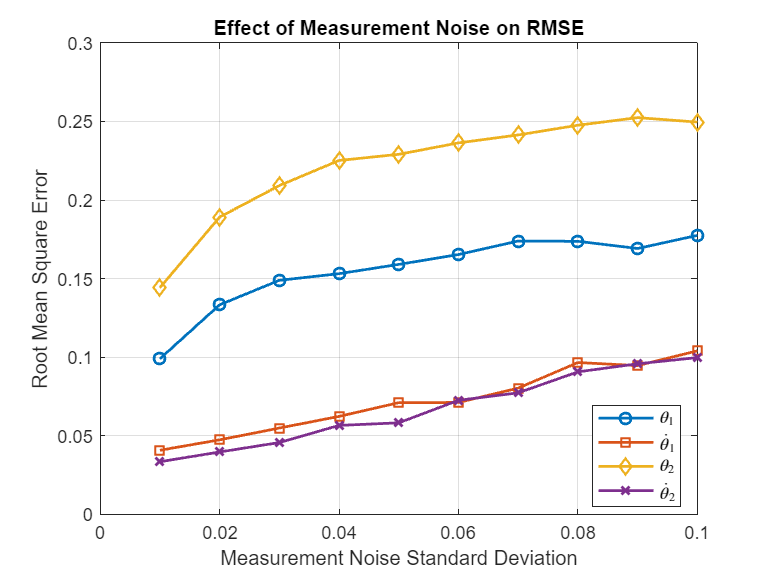

figure;
plot(noise_levels, rmse_results(:, 1), '-o', 'DisplayName', '$\theta_1$', 'LineWidth', 1.5);
hold on;
plot(noise_levels, rmse_results(:, 2), '-s', 'DisplayName', '$\dot{\theta}_1$', 'LineWidth', 1.5);
plot(noise_levels, rmse_results(:, 3), '-d', 'DisplayName', '$\theta_2$', 'LineWidth', 1.5);
plot(noise_levels, rmse_results(:, 4), '-x', 'DisplayName', '$\dot{\theta}_2$', 'LineWidth', 1.5);
xlabel('Measurement Noise Standard Deviation');
ylabel('Root Mean Square Error');
title('Effect of Measurement Noise on RMSE');
legend('Location','best', 'Interpreter', 'Latex');
grid on;
hold off;